## The Penny Myth

You might have heard that a penny dropped from the top of the Empire State Building would be going so fast when it hit the pavement that it would be embedded in the concrete; or if it hit a person, it would break their skull.

We can test this myth by making and analyzing a model.  To get started, we'll assume that the effect of air resistance is small.  This will turn out to be a bad assumption, but bear with me.

If air resistance is negligible, the primary force acting on the penny is gravity, which causes the penny to accelerate downward.

If the initial velocity is 0, the velocity after $t$ seconds is $a t$, and the distance the penny has dropped is


$$h = a t^2 / 2$$


Using algebra, we can solve for $t$:


$$ t = \sqrt{ 2 h / a}$$


Plugging in the acceleration of gravity, $a = 9.8 \mathrm{m / s^2}$, and the height of the Empire State Building,$ h = 381 \mathrm{m}$, we get the time for the penny to drop:

a = 9.8 % m/s^2

a = 9.8000

h = 381 % m

h = 381

t = sqrt(2*h/a) % s

t = 8.8179

Then computing $v = a t$ we get velocity on impact:

v = a * t % m/s

v = 86.4153

 which is about 190 miles per hour.  That sounds like it could hurt.

### A better model

Fortunately for the sidewalk, and the skulls of pedestrians, that result is not accurate because it is based on an unrealistic model.  

In reality, once the penny gets to about 18 m/s, the upward force of air resistance equals the downward force of gravity, so the penny stops accelerating.  After that, it doesn't matter how far the penny falls; it hits the sidewalk at about 18 m/s, much less than 86 m/s.

As an approximation, let's assume that the penny accelerates with constant acceleration $a = 9.8 \mathrm{m / s^2}$ until it reaches terminal velocity, then falls with constant velocity until it hits this sidewalk.

We can use this model to estimate the time it takes to reach the sidewalk.  The time it takes to reach terminal velocity is

v_term = 18 % m / s

v_term = 18

t1 = v_term / a % s

t1 = 1.8367

During that time, the distance it falls is

h1 = a * t1^2 / 2 % m

h1 = 16.5306

The time it takes to fall the remaining distance is

h2 = h - h1 % m

h2 = 364.4694

t2 = h2 / v_term % s

t2 = 20.2483

So the total time is

t_model2 = t1 + t2 % s

t_model2 = 22.0850

Which is substantially longer than 8.8 s.

### Yet another model

The model in the previous section is better, but in reality, drag force increases with velocity, so it takes the penny longer to reach terminal velocity.  

We can make a better model using the drag equation


$$F_d = \frac{1}{2}~\rho~v^2~C_d~A$$


where

- $$F_d$$ is force due to drag, in newtons (N).

- $$\rho$$ is the density of the fluid in $\mathrm{kg / m^3}$.

- $$v$$ is the magnitude of velocity in m/s.

- $$A$$ is the **reference area** of the object, in $\mathrm{m^2}$.  In this context, the reference area is the projected frontal area, that is, the visible area of the object as seen from a point on its line of travel (and far away).

- $$C_d$$ is the **drag coefficient**, a dimensionless quantity that depends on the shape of the object (including length but not frontal area), its surface properties, and how it interacts with the fluid.

For objects moving at moderate speeds through air, typical drag coefficients are between 0.1 and 1.0, with blunt objects at the high end of the range and streamlined objects at the low end (see [https://en.wikipedia.org/wiki/Drag_coefficient](https://en.wikipedia.org/wiki/Drag_coefficient)).

For simple geometric objects we can sometimes guess the drag coefficient with reasonable accuracy; for more complex objects we usually have to take measurements and estimate $$C_d$$ from data.

For the falling penny, we can use measurements to estimate $$C_d$$.   In particular, we can measure terminal velocity, $$v_{term}$$, which is the speed where drag force equals force due to gravity:


$$%
\[ \frac{1}{2}~\rho~v_{term}^2~C_d~A = m g \]
%$$


where $$m$
$ is the mass of the object and $$g$$ is acceleration due to gravity.  Solving this equation for $$C_d$$ yields:


$$%
\[ C_d = \frac{2~m g}{\rho~v_{term}^2~A} \]
%$$


According to *Mythbusters*, the terminal velocity of a penny is between 35 and 65 mph (see [https://en.wikipedia.org/wiki/MythBusters_(2003_season)#Penny_Drop](https://en.wikipedia.org/wiki/MythBusters_(2003_season)#Penny_Drop)).  Using the low end of their range, 40 mph or about 18 m/s, the estimated value of $$C_d$$ is 

g = 9.8          % m/s^2

g = 9.8000

mass = 2.5e-3    % kg

mass = 0.0025

diameter = 19e-3 % m

diameter = 0.0190

rho = 1.2        % kg/m^3

rho = 1.2000

v_term = 18      % m / s

v_term = 18

A = pi * (diameter / 2)^2

A = 2.8353e-04

C_d = 2 * mass * g / rho / v_term^2 / A

C_d = 0.4445

which is close to the drag coefficient of a smooth sphere.

Now we are ready to add air resistance to the model.  If you scroll down to the end of this  script, you'll find a function that computes the acceleration of the penny, taking into account drag, which depends on acceleration.

We can call this function directly, like this:

t = 0;
X = [381, 0];
rate_func(t, X)

ans =          0
   -9.8000


X is a vector with two elements, position and velocity; the result is a vector with two elements, velocity and acceleraton.

Using this function, we can run ode45, which simulates the flight of the penny until it reaches the sidewalk.  event_func is a function that tells ode45 when to stop.

tspan = [0, 30];
options = odeset('Events', @event_func);
[T, M] = ode45(@rate_func, tspan, X, options);

T is a vector of timestamps; M is a matrix with two columns, one for position and one for velocity.  We can extract the columns like this:

Y = M(:, 1);
V = M(:, 2);

If we plot V as a function of time, we see that the penny accelerates until it reaches terminal velocity, which is negative because it's downward.

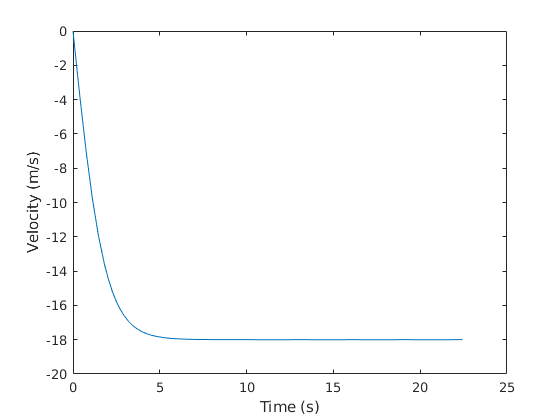

plot(T, V)
xlabel('Time (s)')
ylabel('Velocity (m/s)')

If we plot Y as a function of time, we see that height decreases linearly after the penny reaches terminal velocity.

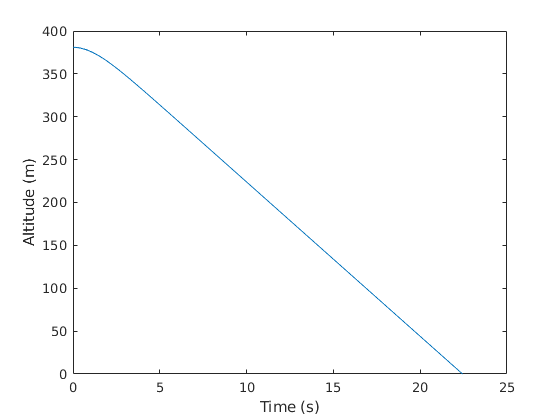

plot(T, Y)
xlabel('Time (s)')
ylabel('Altitude (m)')

The last value of M confirms that the final height is 0 m and the final velocity is close to $$v_{term}$
$.

M(end, :)

ans =    -0.0000  -17.9992


The last value of T shows the time in the air.

t_model3 = T(end)  % s

t_model3 = 22.4396

The result is 22.4 s, which is close to what we got with the second model, 22.1 s.

abs_error = t_model2 - t_model3  % s

abs_error = -0.3546

rel_error = abs_error / t_model3 % dimensionless

rel_error = -0.0158

percent_error = rel_error * 100  % percentage

percent_error = -1.5801

The relative error is less than 2%, which is good enough for many practical purposes.

It is also small enough that it is probably not the biggest source of error.  Remember that our estimate of terminal velocity comes from an experiment with a wide margin of error.  Our estimate for the coefficient of drag could be off by 10% or more.

And the density of air depends on the weather.  The difference between a cold day with high humidity and a hot day with low humidity could be another 10% or more.

Of course, the drag equation is itself a model, based on the assumption that $$C_d$$ does not depend on the other terms in the equation: density, velocity, and area.  For objects moving in air at moderate speeds, the coefficient of drag might vary by another 10%

For any physical system, there are many possible models.  Each model takes some factors into account and ignores others.  All models are based on simplifications and approximations, so in that sense, all models are wrong.

But if we take into account the most important factors and ignore the rest, we can get a model that's good enough.

In this example, if we ignore air resistance completely, the model is very wrong.  The time and velocity it predicts are off by a factor of 3-4.

With a simple model of air resistance, we get an estimate that is off by 2%, which is probably good enough.  And if it's not, there are bigger sources of error we would have to address.

### Functions

function res = rate_func(t, X)
    % Compute acceleration of a falling penny.
    g = 9.8;          % m/s^2
    mass = 2.5e-3;    % kg
    diameter = 19e-3; % m
    rho = 1.2;        % kg/m^3
    v_term = 18;      % m / s
    A = pi * (diameter / 2)^2;
    C_d = 2 * mass * g / rho / v_term^2 / A;

    % unpack position and velocity
    y = X(1);      
    v = X(2);      
    
    % compute force and acceleration
    f_drag = rho * v^2 * C_d * A / 2;
    a_drag = f_drag / mass;
    
    % compute the derivatives
    dydt = v;
    dvdt = -g + a_drag;

    % pack the derivatives into a column vector
    res = [dydt; dvdt];
end

function [value, isterminal, direction] = event_func(t, X)
    % Event function for falling penny.
    value = X(1);
    isterminal = 1;
    direction = -1;
end